# Clement 3

## param

h=1; % le pas
Tcontour=10; % temperature de contour
laplacien=-50; % =-phi/lambda dont phi est puissance de chauffage et lambda est la conductivité thermique de lair


## A

A1=diag(-4*ones(31,1))+diag(ones(30,1),-1)+diag(ones(30,1),1)

A1 =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -4     1     0     0     0

A2=diag(ones(31,1))

A2 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0

A3=zeros(31)

A3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0

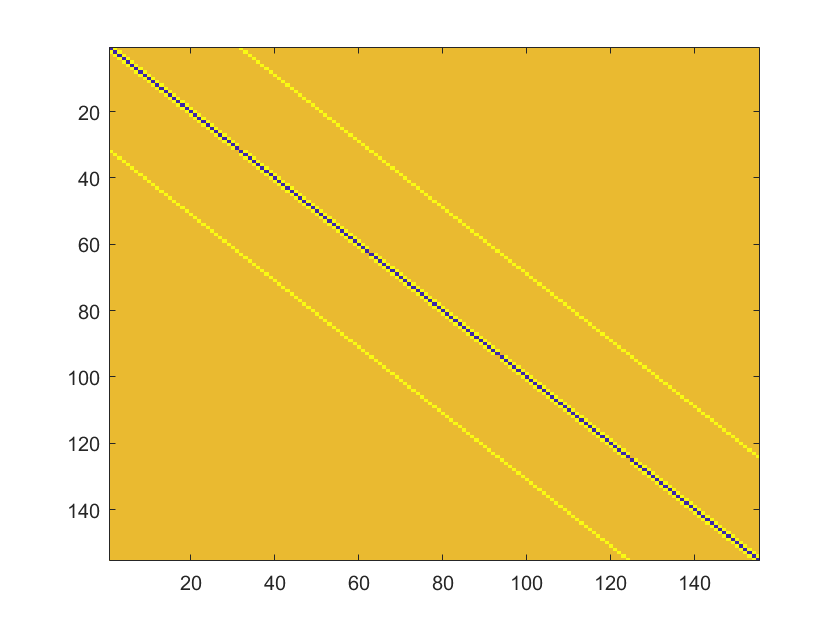

A=[A1 A2 A3 A3 A3;
   A2 A1 A2 A3 A3;
   A3 A2 A1 A2 A3;
   A3 A3 A2 A1 A2;
   A3 A3 A3 A2 A1];
imagesc(A)

## C

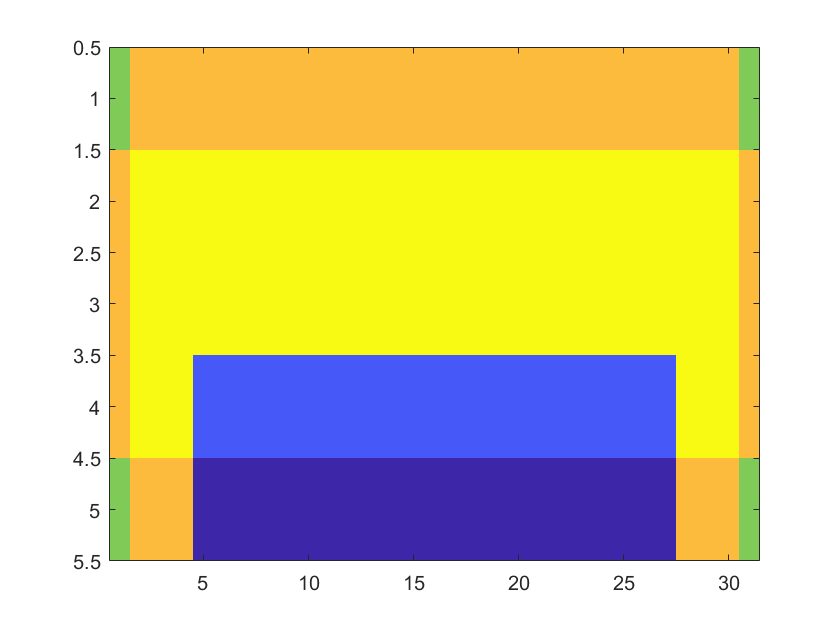

temp=zeros(5,31); % temp veut dire temporaire
temp(1,:)=temp(1,:)-10;
temp(5,:)=temp(5,:)-10;
temp(:,1)=temp(:,1)-10;
temp(:,31)=temp(:,31)-10;
temp(4:5,5:27)=temp(4:5,5:27)+h^2*laplacien;
imagesc(temp)

% décomposer la matrice temp à vecteur C
C=zeros(135,1)

C =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:5
    C(1+(i-1)*31:31+(i-1)*31)=temp(i,:);
end
C

C =    -20
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10


## Tvec

Tvec=A\C;


## Z

Z=zeros(7,33);
Z(1,:)=10;
Z(7,:)=10;
Z(:,1)=10;
Z(:,33)=10;
for i=2:6
    Z(i,2:32)=Tvec(1+(i-2)*31:31+(i-2)*31);
end
Z

Z =    10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000
   10.0000   11.8976   14.1149   16.9164   20.3841   24.1963   27.5547   30.1111   31.8906   33.0628   33.8084   34.2716   34.5543   34.7232   34.8202   34.8700   34.8852   34.8700   34.8202   34.7232   34.5543   34.2716   33.8084   33.0628   31.8906   30.1111   27.5547   24.1963   20.3841   16.9164   14.1149   11.8976   10.0000
   10.0000   13.4755   17.6457   23.1665   30.4239   38.8463   45.9113   50.9990   54.3886   56.5523   57.8990   58.7238   59.2223   59.5184   59.6878   59.7744   59.8009   59.7744   59.6878   59.5184   59.2223   58.7238   57.8990   56.5523   54.3886   50.9990   45.9113   38.8463   30.4239   23.1665   17.6457   13.4755   10.0000
   

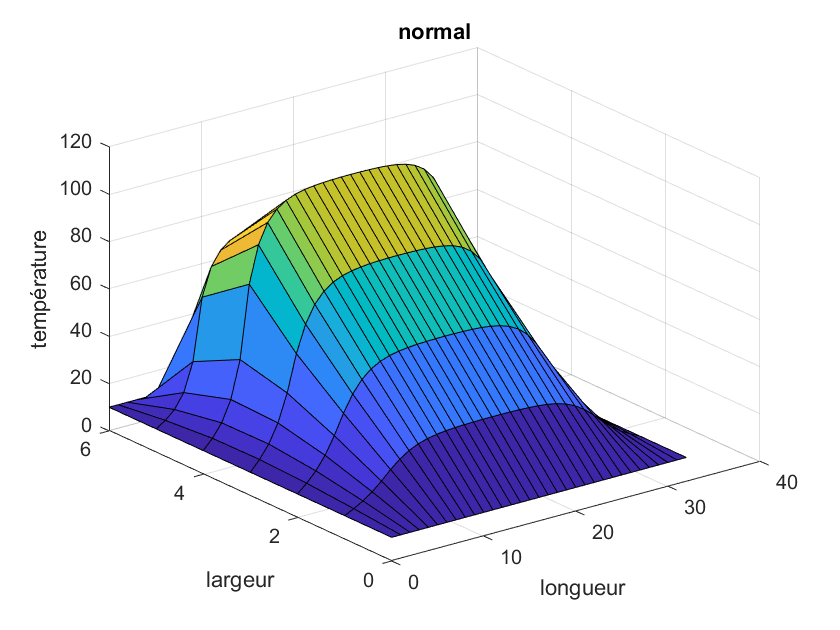

figure(1)
[xq,yq]=meshgrid(0:32,0:6);
surf(xq,yq,Z)
xlabel('longueur'); ylabel('largeur'); zlabel('température');
title('normal')

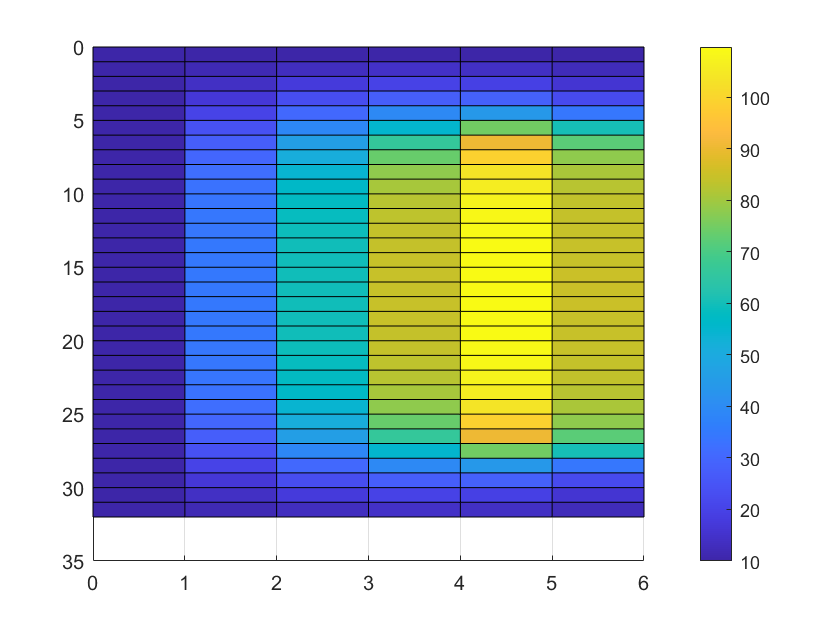

figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar

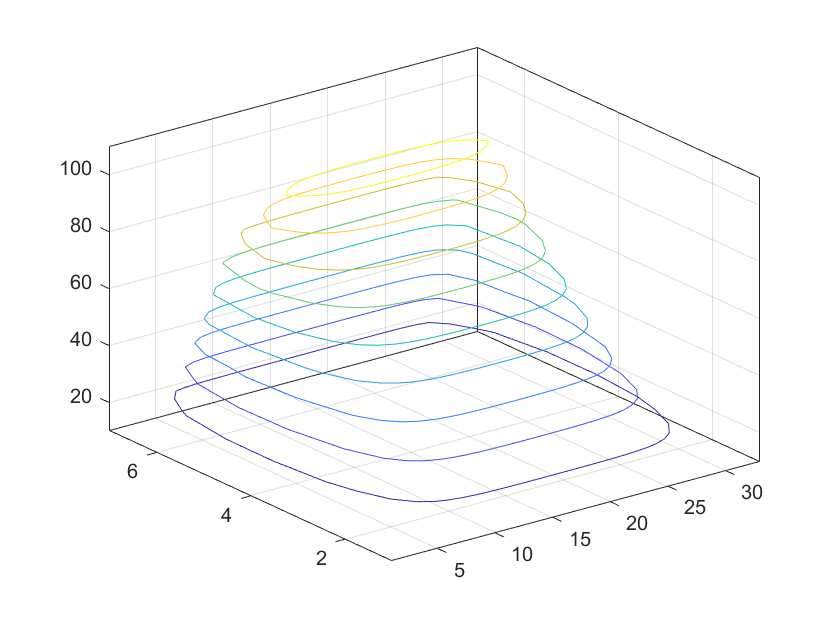

figure(3)
contour3(Z)